Ines Alejandro Garcia Mosqueda A00834571

Cesar Arnaldo Cabrera Chavez A01642244

Davide Dunne Sanchez  A01642355

Benjamin Gutierrez Mndoza A01642356

**limpieza de variables y consola**

close all
clearvars
clear


**Caracteristicas de las laminas**

orden: lamina azul, lamina roja

x1 , x2 ->  espesor placa

y1, y2 -> profundidad lamina

z1, z2 -> altura lamina

dx1, dx2 -> desplazamiento en x respecto a 0

dy1, dy2 -> desplazamiento en y respecto a 0

dz1, dz2 -> desplazamiento en z respecto a 0


%Modifica Lámina Azul
x1 =0.1;
y1 = 6.1;
z1 = 4.1;

dx1 = 2;
dy1 = 0;
dz1 = 0;

%Modifica Lámina Roja
x2 =0.1;
y2 = 3.1;
z2 = 4.1;

dx2 = -2;
dy2 = 0;
dz2 = 0;

%Distancia entre placas
disp(dx1 - dx2);

     4



disp(dy1 - dy2);

     0



disp(dz1 - dz2);

     0



**Creacion de laminas **

desde la funcion Generar_lamina la cua genera una placa de las medidas dadas y en la posicion dada en los parametros


hold on

Generar_lamina(x1,y1,z1,dx1,dy1,dz1,'r');
Generar_lamina(x2,y2,z2,dx2,dy2,dz2,'b');


**Limites de la grafica**

definicion de limites en la grafica (cuadradas)

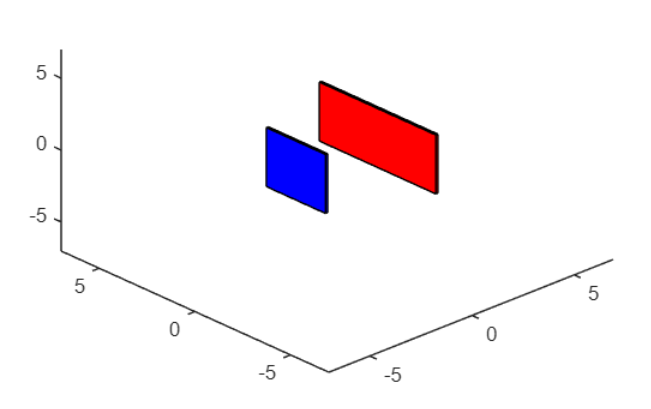


xAx= 7;
yAx = 7;
zAx = 7;
xmin = -xAx;
xmax = xAx;
ymin = -yAx;
ymax = yAx;
zmin = -zAx;
zmax = zAx;
axis([xmin, xmax, ymin, ymax, zmin,zmax]);


**Grid de grafico**

Creacion del manto sobre el cual se grafica un campo vectorial (campo electrico)


[xx,yy] = meshgrid(xmin:0.4:xmax, ymin:0.4:ymax);
zz = xx*0;


**Cargas y constantes**

Definicion de las magnitudes de las cargas y constantes 

- Carga negativa

- Carga positiva

- Constante de coulumb

- Radio de los globulos


qn1 = -20;
qp1 = 20;
k = 8.99e9;
cd = 1.00051;
radioGlobulo = 0.3;


**Cargas de la placa**

Cambio electrico generado por cargas positivas y negativas en x, y, z


    Exp = 0;
    Eyp = 0;
    Ezp = 0;

    Exn = 0;
    Eyn = 0;
    Ezn = 0;


**Llenar las placas con cargas de igual magnitud y signo**

**Devuelve el calculo del campo vectorial en sus componentes rectangulares ( Ex, Ey, Ez ) del campo general **

**Grafica campo vectorial ( campo electrico )**

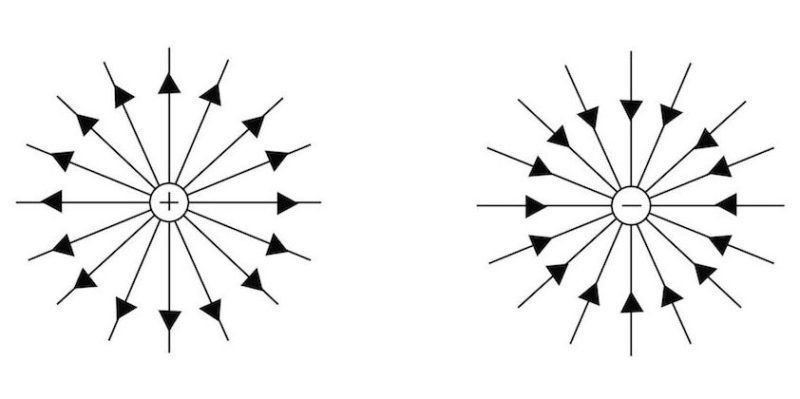

Cuando las cargas son neegativas las lineas de campo van hacia adentro de la carga, cuando son positivas las lineas de campo van hacia afuera

Siendo el campo electrico la sumatoria de los componentes de cada campo electrico generado por cada carga

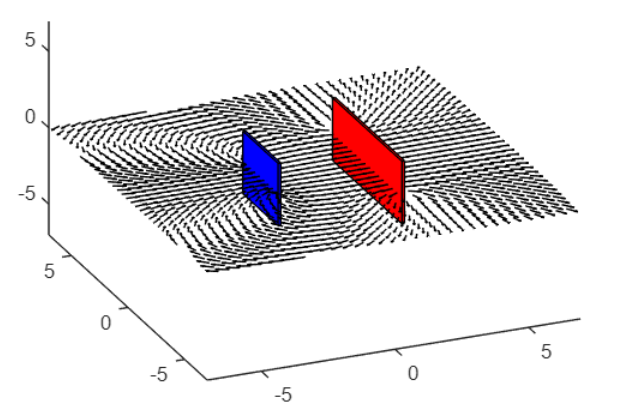

% Cargando placa azul con qn1
for i = -y1/2 : 0.1 : y1/2
    [Exp1, Eyp1, Ezp1] = Particula( qp1,xx,yy,zz,-dx1, i -dy1, dz1);
    Exp = Exp1 + Exp;
    Eyp = Eyp1 + Eyp;
    Ezp = Ezp1 + Ezp;
end

% Cargando placa roja con qp1
for i = -y2/2 : 0.1 : y2/2
    [Exn1, Eyn1, Ezn1] = Particula( qn1,xx,yy,zz,-dx2, i -dy2, dz2);
    Exn = Exn1 + Exn;
    Eyn = Eyn1 + Eyn;
    Ezn = Ezn1 + Ezn;
end

% Sumatoria de campos positivos con campos negativos
Ex = (Exp + Exn);
Ey = (Eyp + Eyn);
Ez = (Ezp + Ezn);

E = sqrt(Ex.^2 + Ey.^2 + Ez.^2);

% Calculo de matriz de los vectores en i, j, k
vi = Ex./E;
vj = Ey./E;
vk = Ez./E.*0;

h = quiver3(xx, yy, zz, vi, vj, vk, 'k');


**Definicion de limites para generacion de globulos en la entrada de las placas**

(entre placa azul y placa roja; arriba de la mitad de ambas placas) 


rX = [round((dx1+(x1/2)-radioGlobulo*2)*100), round((dx2+(x2/2)+radioGlobulo*2)*100)];
rY = [round((dy1+(y1/2)-radioGlobulo*2)*100), round((dy2+(y2/2)+radioGlobulo*2)*100)];


**Numero de globulos, datos de globulos y graficacion**

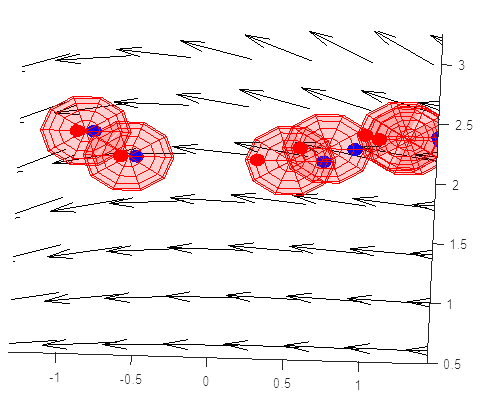


i = 1;     % variable de iteracion
numGlobulos = 5;

% arrays de campos de cada globulo
% array de distancia de cada globulo
campos = [];
distancia = [];

% Creacion y graficacion de cantidad de globulos indicados
% Obtencion de datos de campo electrico y distancia de cada globulo
while i < numGlobulos+1
disp("----------------------")
    disp("Globulo")
    i
[c, d, E] = Globulo(rX, rY, 0.3, false);

campos(i) = E;
distancias(i) = d;
i = i + 1;

end

----------------------


Globulo


i = 1

Distancia entre cargas
    0.6400

Campo electrico del globulo
   3.2493e+12



----------------------


Globulo


i = 2

Distancia entre cargas
    0.5500

Campo electrico del globulo
   5.2834e+12



----------------------


Globulo


i = 3

Distancia entre cargas
   -1.0200

Campo electrico del globulo
   6.1428e+11



----------------------


Globulo


i = 4

Distancia entre cargas
   -0.4000

Campo electrico del globulo
   4.0055e+12



----------------------


Globulo


i = 5

Distancia entre cargas
    0.7600

Campo electrico del globulo
   1.5730e+12



**Calculo de promedio de campo electrico para evaluar infeccion**

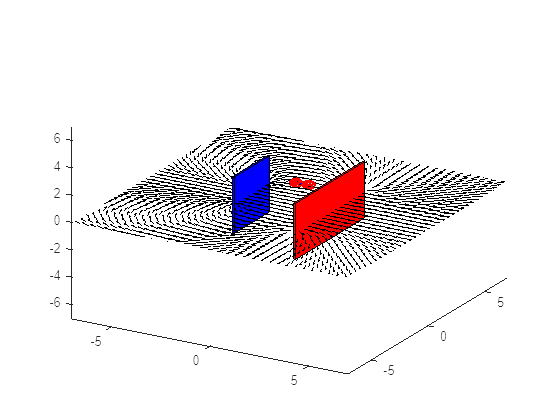

Distancia entre cargas
    0.6100



[c, d, E] = Globulo(rX, rY, 0.3, true);

disp("Valor sobre el cual es el limite de campo electrico entre un globulo sano y una infectado ")

Valor sobre el cual es el limite de campo electrico entre un globulo sano y una infectado 


xProm = E;
E

E = 1.8699e+12

**Grafica de resultado con cargas infectadas**

figure(2)
hold on
axis([xmin, xmax, ymin, ymax, zmin,zmax]);
Generar_lamina(x1,y1,z1,dx1,dy1,dz1,'r');
Generar_lamina(x2,y2,z2,dx2,dy2,dz2,'b');
    Exp = 0;
    Eyp = 0;
    Ezp = 0;

    Exn = 0;
    Eyn = 0;
    Ezn = 0;

for i = -y1/2 : 0.1 : y1/2
    [Exp1, Eyp1, Ezp1] = Particula( qp1,xx,yy,zz,-dx1, i -dy1, dz1);
    Exp = Exp1 + Exp;
    Eyp = Eyp1 + Eyp;
    Ezp = Ezp1 + Ezp;
end

for i = -y2/2 : 0.1 : y2/2
    [Exn1, Eyn1, Ezn1] = Particula( qn1,xx,yy,zz,-dx2, i -dy2, dz2);
    Exn = Exn1 + Exn;
    Eyn = Eyn1 + Eyn;
    Ezn = Ezn1 + Ezn;
end


Ex = (Exp + Exn);
Ey = (Eyp + Eyn);
Ez = (Ezp + Ezn);
 
E = sqrt(Ex.^2 + Ey.^2 + Ez.^2);

vi = Ex./E;
vj = Ey./E;
vk = Ez./E.*0;

h = quiver3(xx, yy, zz, vi, vj, vk, 'k');


**Evaluar glonulos infectados**


infectados = [];
i=1;

while i < numGlobulos+1

if campos(i) > xProm
    infectados(end+1) = distancias(i);
    disp("----------------------")
    disp("Globulo")
    i
    disp("Globulo infectado")
    disp("Distancia entre cargas:")
    distancias(i)
    disp("Campo electrico resultante:")
    campos(i)
end
i = i + 1;
end

----------------------


Globulo


i = 1

Globulo infectado


Distancia entre cargas:


ans = 0.2104

Campo electrico resultante:


ans = 3.2493e+12

----------------------


Globulo


i = 2

Globulo infectado


Distancia entre cargas:


ans = 0.1650

Campo electrico resultante:


ans = 5.2834e+12

----------------------


Globulo


i = 4

Globulo infectado


Distancia entre cargas:


ans = 0.1895

Campo electrico resultante:


ans = 4.0055e+12

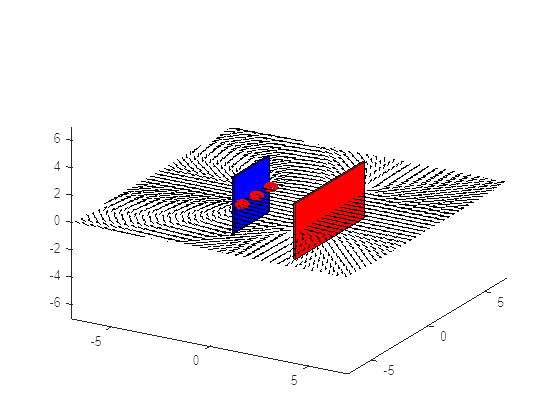


posY_infectados = linspace(-y2/2+radioGlobulo, y2/2-radioGlobulo, length(infectados));
posX_infectados = dx2 + radioGlobulo;

for i = 1: length(infectados)
    GlobuloExistente(posX_infectados, posY_infectados(i), radioGlobulo, infectados(i));
end

**Creacion de una lamina con medidas y color introducido en el parametro**

function Generar_lamina(x,y,z,dx,dy,dz,color)

    verticesR = [
    (-x/2)+dx,(-y/2)+dy,(-z/2)+dz; %v1
    (x/2)+dx,(-y/2)+dy,(-z/2)+dz; %v2
    (x/2)+dx,(y/2)+dy,(-z/2)+dz; %v3
    (-x/2)+dx,(y/2)+dy,(-z/2)+dz; %v4
    (-x/2)+dx,(-y/2)+dy,(z/2)+dz; %v5
    (x/2)+dx,(-y/2)+dy,(z/2)+dz; %v6
    (x/2)+dx,(y/2)+dy,(z/2)+dz; %v7
    (-x/2)+dx,(y/2)+dy,(z/2)+dz; %v8
    ];
carasR = [
    1,2,6,5;
    2,3,7,6;
    3,4,8,7;
    4,8,5,1;
    5,6,7,8;
    1,2,3,4;
];

patch('Faces',carasR, 'Vertices',verticesR,'FaceColor',color);
view(30,30);
end


**Creacion de componentes de los campos electricos creados por cargas en toada la meshgrid**

function [Ex, Ey, Ez] = Particula(carga, xx, yy, zz, x, y, z)
    k = 8.99e9;
    Rx = xx + x;
    Ry = yy + y;
    Rz = zz + z;
    R = sqrt(Rx.^2 + Ry.^2 + Rz.^2) .^ 3;

    Ex = k.*carga.*Rx./R;
    Ey = k.*carga.*Ry./R;
    Ez = k.*carga.*Rz./R;
end


**Creacion de globulos  a partir de los parametros limitantes en "x" e "y"**

function [carga, posCG, E] = Globulo(rX, rY, rg, iniciales)

% Posicion random del globulo X e Y 
    posXG=(randi([rX(2), rX(1)],1,1))/100;
    posYG=(randi([rY(2), rY(1)],1,1))/100;

% Parametros del globulo
    RadioGlobulo=rg;
    RadioCargas=0.05;
    carga = 4;

% Creacion de carga aleatoria
    %carga = 1- (0.5*rand());

% Creacion de esfera globulo
    [x,y,z]=sphere(10);
    x=x*RadioGlobulo;
    y=y*RadioGlobulo;
    z=z*RadioGlobulo;
    surf(x+posXG,y+posYG,z,'FaceColor','r','EdgeColor','r','FaceAlpha','0.1');
    
% Distancia aleatoria entre cargas

if iniciales == true
    min = 2*RadioCargas;
    max = 2*RadioGlobulo- 2*RadioCargas;
    posCG = min;
else
    min = round((RadioCargas*2)*10000);
    max = round((2*RadioGlobulo-2*RadioCargas)*10000);
    SeparacionCargas =  (randi([min,max]));
    posCG = SeparacionCargas/10000;
end

% Creacion de esfera carga negativa
    hold on
    [x,y,z]=sphere(10);
    x=x*RadioCargas;
    y=y*RadioCargas;
    z=z*RadioCargas;
    surf(x+posXG+(posCG)/2,y+posYG,z,'FaceColor','b','EdgeColor','b','FaceAlpha','1');

% Creacion de esfera carga positiva
    hold on
    [x,y,z]=sphere(10);
    x=x*RadioCargas;
    y=y*RadioCargas;
    z=z*RadioCargas;
    surf(x+posXG-(posCG)/2,y+posYG,z,'FaceColor','r','EdgeColor','r','FaceAlpha','1');
    disp("Distancia entre cargas")
    disp(posXG)    
    
%Generacion de cargas 
    k = 8.99e9;

if iniciales == true
    posCG = min;
    Exp1 = k*carga/(posCG)^2;


    posCG = max;
    Exp2 = k*carga/(posCG)^2;
    E = (Exp1 + Exp2)/2;

else
    Exp = k*carga/(posCG/2)^2;
    disp("Campo electrico del globulo")
    disp(Exp)
    E = Exp;

end
end


**Graficacion de globulos a partir de parametros ya existentes**


function GlobuloExistente(x, y, rg, dCG)

% Posicion random del globulo X e Y 
    posXG = x;
    posYG = y;

% Parametros del globulo
    RadioGlobulo=rg;
    RadioCargas=0.05;
    carga = 2;

% Creacion de esfera globulo
    [x,y,z]=sphere(10);
    x=x*RadioGlobulo;
    y=y*RadioGlobulo;
    z=z*RadioGlobulo;
    surf(x+posXG,y+posYG,z,'FaceColor','r','EdgeColor','r','FaceAlpha','0.1');
    
% Distancia entre cargas

    posCG = dCG;

% Creacion de esfera carga negativa
    hold on
    [x,y,z]=sphere(10);
    x=x*RadioCargas;
    y=y*RadioCargas;
    z=z*RadioCargas;
    surf(x+posXG+(posCG),y+posYG,z,'FaceColor','b','EdgeColor','b','FaceAlpha','1');

% Creacion de esfera carga positiva
    hold on
    [x,y,z]=sphere(10);
    x=x*RadioCargas;
    y=y*RadioCargas;
    z=z*RadioCargas;
    surf(x+posXG-(posCG),y+posYG,z,'FaceColor','r','EdgeColor','r','FaceAlpha','1');

end

